clc
clear all
close all

## training data

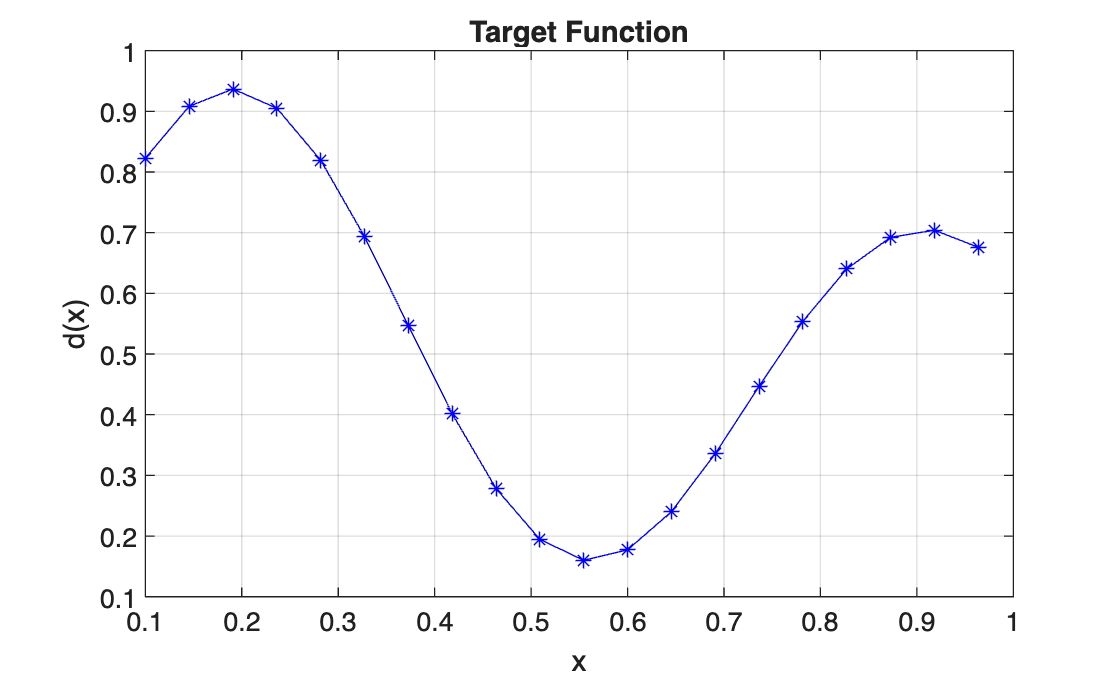

x = 0.1:1/22:1;                                     
d = (1 + 0.6*sin(2*pi*x/0.7) + 0.3*sin(2*pi*x))/2;
figure; 
plot(x,d,'b-*'); 
title('Target Function'); xlabel('x'); ylabel('d(x)'); grid on

## Parameters

% Hidden layer weights (6 neurons, layer 1)
w11_1 = rand(1);   % input -> hidden neuron1
w21_1 = rand(1);   % input -> hidden neuron2
w31_1 = rand(1);   % input -> hidden neuron3
w41_1 = rand(1);   % input -> hidden neuron4
w51_1 = rand(1);   % input -> hidden neuron5
w61_1 = rand(1);   % input -> hidden neuron6

% Hidden layer biases
b1_1  = rand(1);   % bias neuron1
b2_1  = rand(1);   % bias neuron2
b3_1  = rand(1);   % bias neuron3
b4_1  = rand(1);   % bias neuron4
b5_1  = rand(1);   % bias neuron5
b6_1  = rand(1);   % bias neuron6

% Output layer weights (from 6 hidden neurons to output, layer 2)
w11_2 = rand(1);   % hidden1 -> output
w12_2 = rand(1);   % hidden2 -> output
w13_2 = rand(1);   % hidden3 -> output
w14_2 = rand(1);   % hidden4 -> output
w15_2 = rand(1);   % hidden5 -> output
w16_2 = rand(1);   % hidden6 -> output

% Output layer bias
b1_2  = rand(1);   % output neuron bias

eta = 0.1;         % learning rate 

## Training

for ep = 1:2000000
    for i = 1:length(x)

        % Feedforward
        % Hidden layer net inputs
        v1_1 = x(i)*w11_1 + b1_1; % weighted sum1 -> layer2
        v2_1 = x(i)*w21_1 + b2_1; % weighted sum2 -> layer2
        v3_1 = x(i)*w31_1 + b3_1; % weighted sum3 -> layer2
        v4_1 = x(i)*w41_1 + b4_1; % weighted sum4 -> layer2
        v5_1 = x(i)*w51_1 + b5_1; % weighted sum5 -> layer2
        v6_1 = x(i)*w61_1 + b6_1; % weighted sum6 -> layer2

        % Hidden layer activations
        y1_1 = 1/(1 + exp(-v1_1));
        y2_1 = 1/(1 + exp(-v2_1));
        y3_1 = 1/(1 + exp(-v3_1));
        y4_1 = 1/(1 + exp(-v4_1));
        y5_1 = 1/(1 + exp(-v5_1));
        y6_1 = 1/(1 + exp(-v6_1));

        % Output layer (linear)
        v1_2 = y1_1*w11_2 + y2_1*w12_2 + y3_1*w13_2 + y4_1*w14_2 + y5_1*w15_2 + y6_1*w16_2 +b1_2;
        y1_2 = v1_2;      % linear activation

        % Error
        e = d(i) - y1_2;

        % Backpropagation
        % Output layer delta (linear -> derivative = 1)
        delta1_2 = e;

        % Hidden layer deltas (sd -> y*(1-y))
        delta1_1 = y1_1*(1 - y1_1) * delta1_2 * w11_2;
        delta2_1 = y2_1*(1 - y2_1) * delta1_2 * w12_2;
        delta3_1 = y3_1*(1 - y3_1) * delta1_2 * w13_2;
        delta4_1 = y4_1*(1 - y4_1) * delta1_2 * w14_2;
        delta5_1 = y5_1*(1 - y5_1) * delta1_2 * w15_2;
        delta6_1 = y6_1*(1 - y6_1) * delta1_2 * w16_2;

        % Update Weight
        % Output layer
        w11_2 = w11_2 + eta*delta1_2*y1_1;
        w12_2 = w12_2 + eta*delta1_2*y2_1;
        w13_2 = w13_2 + eta*delta1_2*y3_1;
        w14_2 = w14_2 + eta*delta1_2*y4_1;
        w15_2 = w15_2 + eta*delta1_2*y5_1;
        w16_2 = w16_2 + eta*delta1_2*y6_1;
        b1_2  = b1_2  + eta*delta1_2;

        % Hidden layer
        w11_1 = w11_1 + eta*delta1_1*x(i);
        w21_1 = w21_1 + eta*delta2_1*x(i);
        w31_1 = w31_1 + eta*delta3_1*x(i);
        w41_1 = w41_1 + eta*delta4_1*x(i);
        w51_1 = w51_1 + eta*delta5_1*x(i);
        w61_1 = w61_1 + eta*delta6_1*x(i);

        % biases
        b1_1  = b1_1 + eta*delta1_1;
        b2_1  = b2_1 + eta*delta2_1;
        b3_1  = b3_1 + eta*delta3_1;
        b4_1  = b4_1 + eta*delta4_1;
        b5_1  = b5_1 + eta*delta5_1;
        b6_1  = b6_1 + eta*delta6_1;
    end
end



## Testing

x_test = 0.1:1/220:1;                               
y_test = (1 + 0.6*sin(2*pi*x_test/0.7) + 0.3*sin(2*pi*x_test))/2;
Y_pred = zeros(1,length(x_test));

for i = 1:length(x_test)
    v1_1 = x_test(i)*w11_1 + b1_1;
    v2_1 = x_test(i)*w21_1 + b2_1;
    v3_1 = x_test(i)*w31_1 + b3_1;
    v4_1 = x_test(i)*w41_1 + b4_1;
    v5_1 = x_test(i)*w51_1 + b5_1;
    v6_1 = x_test(i)*w61_1 + b6_1

    y1_1 = 1/(1 + exp(-v1_1));
    y2_1 = 1/(1 + exp(-v2_1));
    y3_1 = 1/(1 + exp(-v3_1));
    y4_1 = 1/(1 + exp(-v4_1));
    y5_1 = 1/(1 + exp(-v5_1));
    y6_1 = 1/(1 + exp(-v6_1));

    Y_pred(i) = y1_1*w11_2 + y2_1*w12_2 + y3_1*w13_2 + y4_1*w14_2 + y5_1*w15_2 + y6_1*w16_2 + b1_2;
end

v6_1 = 4.2886

v6_1 = 4.2694

v6_1 = 4.2503

v6_1 = 4.2311

v6_1 = 4.2120

v6_1 = 4.1928

v6_1 = 4.1737

v6_1 = 4.1545

v6_1 = 4.1354

v6_1 = 4.1162

v6_1 = 4.0971

v6_1 = 4.0779

v6_1 = 4.0588

v6_1 = 4.0396

v6_1 = 4.0205

v6_1 = 4.0013

v6_1 = 3.9822

v6_1 = 3.9630

v6_1 = 3.9439

v6_1 = 3.9247

v6_1 = 3.9056

v6_1 = 3.8864

v6_1 = 3.8673

v6_1 = 3.8481

v6_1 = 3.8290

v6_1 = 3.8098

v6_1 = 3.7907

v6_1 = 3.7715

v6_1 = 3.7524

v6_1 = 3.7332

v6_1 = 3.7141

v6_1 = 3.6949

v6_1 = 3.6758

v6_1 = 3.6567

v6_1 = 3.6375

v6_1 = 3.6184

v6_1 = 3.5992

v6_1 = 3.5801

v6_1 = 3.5609

v6_1 = 3.5418

v6_1 = 3.5226

v6_1 = 3.5035

v6_1 = 3.4843

v6_1 = 3.4652

v6_1 = 3.4460

v6_1 = 3.4269

v6_1 = 3.4077

v6_1 = 3.3886

v6_1 = 3.3694

v6_1 = 3.3503

v6_1 = 3.3311

v6_1 = 3.3120

v6_1 = 3.2928

v6_1 = 3.2737

v6_1 = 3.2545

v6_1 = 3.2354

v6_1 = 3.2162

v6_1 = 3.1971

v6_1 = 3.1779

v6_1 = 3.1588

v6_1 = 3.1396

v6_1 = 3.1205

v6_1 = 3.1013

v6_1 = 3.0822

v6_1 = 3.0630

v6_1 = 3.0439

v6_1 = 3.0247

v6_1 = 3.0056

v6_1 = 2.9864

v6_1 = 2.9673

v6_1 = 2.9481

v6_1 = 2.9290

v6_1 = 2.9099

v6_1 = 2.8907

v6_1 = 2.8716

v6_1 = 2.8524

v6_1 = 2.8333

v6_1 = 2.8141

v6_1 = 2.7950

v6_1 = 2.7758

v6_1 = 2.7567

v6_1 = 2.7375

v6_1 = 2.7184

v6_1 = 2.6992

v6_1 = 2.6801

v6_1 = 2.6609

v6_1 = 2.6418

v6_1 = 2.6226

v6_1 = 2.6035

v6_1 = 2.5843

v6_1 = 2.5652

v6_1 = 2.5460

v6_1 = 2.5269

v6_1 = 2.5077

v6_1 = 2.4886

v6_1 = 2.4694

v6_1 = 2.4503

v6_1 = 2.4311

v6_1 = 2.4120

v6_1 = 2.3928

v6_1 = 2.3737

v6_1 = 2.3545

v6_1 = 2.3354

v6_1 = 2.3162

v6_1 = 2.2971

v6_1 = 2.2779

v6_1 = 2.2588

v6_1 = 2.2396

v6_1 = 2.2205

v6_1 = 2.2014

v6_1 = 2.1822

v6_1 = 2.1631

v6_1 = 2.1439

v6_1 = 2.1248

v6_1 = 2.1056

v6_1 = 2.0865

v6_1 = 2.0673

v6_1 = 2.0482

v6_1 = 2.0290

v6_1 = 2.0099

v6_1 = 1.9907

v6_1 = 1.9716

v6_1 = 1.9524

v6_1 = 1.9333

v6_1 = 1.9141

v6_1 = 1.8950

v6_1 = 1.8758

v6_1 = 1.8567

v6_1 = 1.8375

v6_1 = 1.8184

v6_1 = 1.7992

v6_1 = 1.7801

v6_1 = 1.7609

v6_1 = 1.7418

v6_1 = 1.7226

v6_1 = 1.7035

v6_1 = 1.6843

v6_1 = 1.6652

v6_1 = 1.6460

v6_1 = 1.6269

v6_1 = 1.6077

v6_1 = 1.5886

v6_1 = 1.5694

v6_1 = 1.5503

v6_1 = 1.5311

v6_1 = 1.5120

v6_1 = 1.4928

v6_1 = 1.4737

v6_1 = 1.4546

v6_1 = 1.4354

v6_1 = 1.4163

v6_1 = 1.3971

v6_1 = 1.3780

v6_1 = 1.3588

v6_1 = 1.3397

v6_1 = 1.3205

v6_1 = 1.3014

v6_1 = 1.2822

v6_1 = 1.2631

v6_1 = 1.2439

v6_1 = 1.2248

v6_1 = 1.2056

v6_1 = 1.1865

v6_1 = 1.1673

v6_1 = 1.1482

v6_1 = 1.1290

v6_1 = 1.1099

v6_1 = 1.0907

v6_1 = 1.0716

v6_1 = 1.0524

v6_1 = 1.0333

v6_1 = 1.0141

v6_1 = 0.9950

v6_1 = 0.9758

v6_1 = 0.9567

v6_1 = 0.9375

v6_1 = 0.9184

v6_1 = 0.8992

v6_1 = 0.8801

v6_1 = 0.8609

v6_1 = 0.8418

v6_1 = 0.8226

v6_1 = 0.8035

v6_1 = 0.7843

v6_1 = 0.7652

v6_1 = 0.7461

v6_1 = 0.7269

v6_1 = 0.7078

v6_1 = 0.6886

v6_1 = 0.6695

v6_1 = 0.6503

v6_1 = 0.6312

v6_1 = 0.6120

v6_1 = 0.5929

v6_1 = 0.5737

v6_1 = 0.5546

v6_1 = 0.5354

v6_1 = 0.5163

v6_1 = 0.4971

## plotting

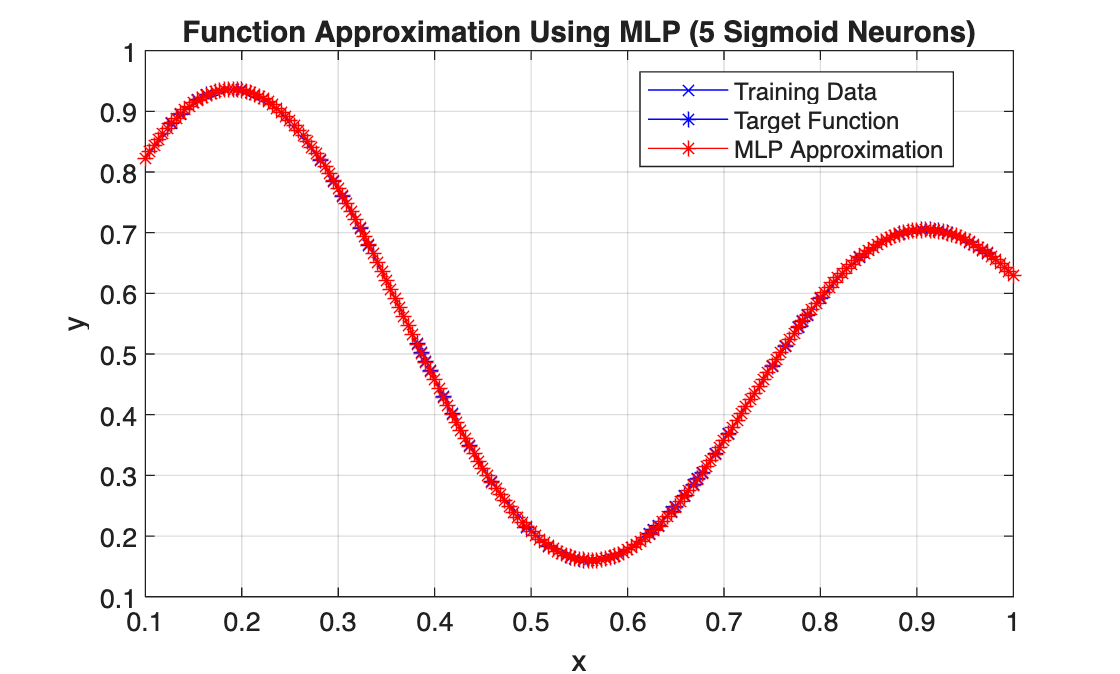

figure;
plot(x,d,'b-x'); 
hold on
plot(x_test,y_test,'b-*');
plot(x_test,Y_pred,'r-*');
legend('Training Data','Target Function','MLP Approximation','Location','best');
title('Function Approximation Using MLP (5 Sigmoid Neurons)'); 
xlabel('x'); ylabel('y'); grid on